# Path Planning for Unicycle Robot using Cubic Cartesian Polynomial

#### ***POINT_1: This code implements a path planning algorithm for a unicycle robot using cubic Cartesian polynomials with explicit time law.***

clear all;
close all;
clc;

***Initial and Final Configuration***

% Initial configuration qi = [xi yi θi]ᵀ = [0 0 0]ᵀ
qi = [0; 0; 0];

To ensure the unit norm constraint between qi and qf , the following code has been used:

% Generate random final configuration qf = [xf yf θf]ᵀ, such that ||qf - qi|| = 1
random_config = rand(1,3);
normalized_config = random_config / norm(random_config);
qf = normalized_config';

The resulting qf is a normalized random configuration vector.

% Display configurations
disp('Initial configuration:');

Initial configuration:


disp(qi');

     0     0     0



disp('Final configuration:');

Final configuration:


disp(qf');

    0.6370    0.7635    0.1062



***Path definition using cubic Cartesian polynomial***

The path in the xy-plane was generated using a cubic polynomial:


$$$$x(s) = s^3x_f - (s - 1)^3x_i + \alpha_x s^2(s - 1) + \beta_x s(s - 1)^2$$

$$y(s) = s^3y_f - (s - 1)^3y_i + \alpha_y s^2(s - 1) + \beta_y s(s - 1)^2$$$$


% Extract coordinates and orientations
x_i = qi(1);
y_i = qi(2);
theta_i = qi(3);
x_f = qf(1);
y_f = qf(2);
theta_f = qf(3);

% Parameter k 
k = 5;  

% Definition of the coefficients alpha_x, alpha_y, beta_x, beta_y
alfa_x = k*cos(theta_f)-3*x_f;
alfa_y = k*sin(theta_f)-3*y_f;
beta_x = k*cos(theta_i)+3*x_i;
beta_y = k*sin(theta_i)+3*y_i;

***Time law implementation***

The trajectory was parameterized over time using a cubic function s(t):


$$s(t) = a_0 + a_1 t + a_2 t^2 + a_3 t^3$$


with the boundary conditions: s(0) = 0, s_dot(0)=0, s(T) = 1, s_dot(T)=0.

% Time setting
T = 10;     % Final time
dt = 0.01;  % Time step for simulation

% Defining time law coefficients for a cubic polynomial s(t) = a₀ + a₁t + a₂t² + a₃t³, with constraints: s(0) = 0, s(T) = 1, s'(0) = 0, s'(T) = 0
a0 = 0;
a1 = 0;
a2 = 3/T^2;
a3 = -2/T^3;

max_iterations = 2;
iteration_count = 0;

% Find a suitable time law
while true
    
    if iteration_count == 1

    % Font sizes
    fontSize = 11;
    titleSize = 12;
    legendSize = 10;
    %% Plot: 
    fig1 = figure('Color', 'white');
    plot(t, v, 'LineWidth', 2)
    hold on
    plot(t, 0.5*ones(size(t)), 'r--')
    plot(t, -0.5*ones(size(t)), 'r--')
    title('\textbf{Linear Velocity Without Time Scaling}', 'FontSize', titleSize, 'Interpreter', 'latex')
    xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
    ylabel('\textbf{Linear Velocity [m/s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
    ylim([-1, 1])
    grid on
    legend('\textbf{Linear Velocity}', '\textbf{Bounds}', 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'best')
    set(gca, 'FontSize', fontSize);
    print(fig1,'-depsc2', 'linear_velocity_without_timescaling.eps');
    
    fig2 = figure('Color', 'white');
    plot(t, omega, 'LineWidth', 2)
    hold on
    plot(t, 2*ones(size(t)), 'r--')
    plot(t, -2*ones(size(t)), 'r--')
    title('\textbf{Angular Velocity Without Time Scaling}', 'FontSize', titleSize, 'Interpreter', 'latex')
    xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
    ylabel('\textbf{$\omega$ [rad/s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
    ylim([-4, 4])
    grid on
    legend('\textbf{Angular Velocity}', '\textbf{Bounds}', 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'best')
    set(gca, 'FontSize', fontSize);
    print(fig2,'-depsc2', 'angular_velocity_without_timescaling.eps');
    
    end

    iteration_count = iteration_count + 1;
    
    % Time vector definition
    t = 0:dt:T;
    
    % s(t) and its derivative computation
    s = a0 + a1*t + a2*t.^2 + a3*t.^3;
    ds_dt = a1 + 2*a2*t + 3*a3*t.^2;
    d2s_dt2 = 2*a2 + 6*a3*t;  
    
    % Preallocate arrays 
    x = zeros(size(t));
    y = zeros(size(t));
    x_dot = zeros(size(t));
    y_dot = zeros(size(t));
    x_ddot = zeros(size(t));
    y_ddot = zeros(size(t));
    theta = zeros(size(t));
    v_tilde = zeros(size(t));
    omega_tilde = zeros(size(t));
    v = zeros(size(t));
    omega = zeros(size(t));


    % Compute path and derivatives for each time point
    for i = 1:length(t)
        si = s(i);
        
        % Calculate position using cubic polynomial path
        x(i) = si.^3.*x_f-(si-1).^3.*x_i+alfa_x.*si.^2.*(si-1)+beta_x.*si.*(si-1).^2;
        y(i) = si.^3.*y_f-(si-1).^3.*y_i+alfa_y.*si.^2.*(si-1)+beta_y.*si.*(si-1).^2;
        
        % First derivatives with respect to s
        x_dot(i) = 3.*si.^2.*x_f-3.*(si-1).^2.*x_i+2.*alfa_x.*si.*(si-1)+alfa_x.*si.^2+beta_x.*(si-1).^2+2.*beta_x.*si.*(si-1);
        y_dot(i) = 3.*si.^2.*y_f-3.*(si-1).^2.*y_i+2.*alfa_y.*si.*(si-1)+alfa_y.*si.^2+beta_y.*(si-1).^2+2.*beta_y.*si.*(si-1);
        
        % Second derivatives with respect to s
        x_ddot(i) = 6.*si.*x_f-6.*(si-1).*x_i+2.*alfa_x.*(si-1)+2.*alfa_x.*si+2.*alfa_x.*si+2.*beta_x.*(si-1)+2.*beta_x.*(si-1)+2.*beta_x.*si;
        y_ddot(i) = 6.*si.*y_f-6.*(si-1).*y_i+2.*alfa_y.*(si-1)+2.*alfa_y.*si+2.*alfa_y.*si+2.*beta_y.*(si-1)+2.*beta_y.*(si-1)+2.*beta_y.*si;
        
        % Compute orientation
        theta(i) = atan2(y_dot(i), x_dot(i));
        
        % Path velocities and accelerations 
        v_tilde(i) = sqrt(x_dot(i)^2 + y_dot(i)^2);
        omega_tilde(i) = (y_ddot(i)*x_dot(i) - x_ddot(i)*y_dot(i))/(x_dot(i)^2 + y_dot(i)^2);
        
        % Actual velocities (with respect to time)
        v(i) = v_tilde(i) * ds_dt(i);
        omega(i) = omega_tilde(i) * ds_dt(i) + (x_dot(i)*y_dot(i) - y_dot(i)*x_dot(i))/(x_dot(i)^2 + y_dot(i)^2) * d2s_dt2(i);
    end


***Velocity bounds***

After computing the first and second derivatives of x and y, it is possible to derive θ, the heading and angular velocities and, then, check if velocity bounds are satisfied.

With T = 10 s:


Maximum linear velocity: 0.27631 m/s


Maximum angular velocity: 2.5073 rad/s


Velocity bounds not satisfied!


Scaling time by factor: 1.2537


New time duration: 12.5366 s


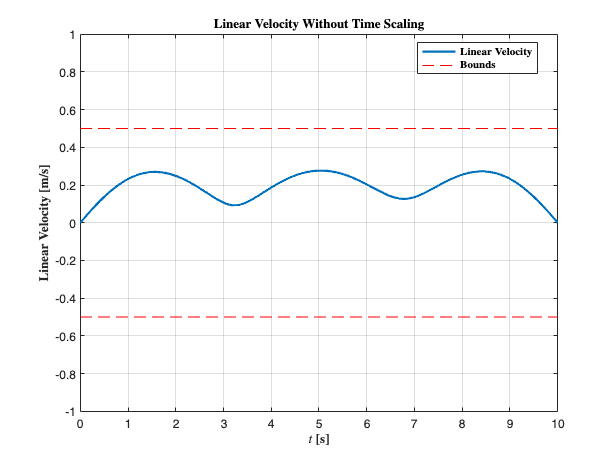

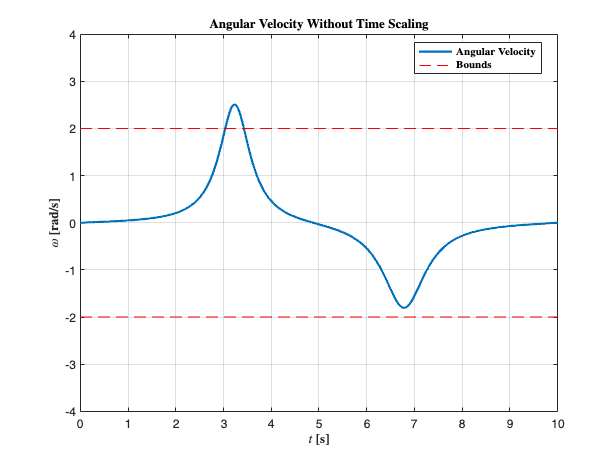

With T = 12.5366 s:


Maximum linear velocity: 0.2204 m/s


Maximum angular velocity: 2 rad/s


Velocity bounds satisfied!


% Check velocity bounds
    max_v = max(abs(v));
    max_omega = max(abs(omega));
    
    disp(['With T = ', num2str(T), ' s:']);
    disp(['Maximum linear velocity: ', num2str(max_v), ' m/s']);
    disp(['Maximum angular velocity: ', num2str(max_omega), ' rad/s']);
    

    % Check if velocity bounds are satisfied
    if max_v <= 0.5 && max_omega <= 2 || iteration_count >= max_iterations
        disp('Velocity bounds satisfied!');
        break;
    else
        % Calculate scaling factor
        scale_factor_v = max_v / 0.5;
        scale_factor_omega = max_omega / 2;
        scale_factor = max(scale_factor_v, scale_factor_omega);
        
        % Update time duration
        T = T * scale_factor;
        
        % Update time law coefficients
        a2 = 3/T^2;
        a3 = -2/T^3;
        
        disp('Velocity bounds not satisfied!');
        disp(['Scaling time by factor: ', num2str(scale_factor)]);
        disp(['New time duration: ', num2str(T), ' s']);

        fid = fopen('output.tex', 'w');
        fprintf(fid, 'Initial configuration: $%s$ \\\\\n', strrep(num2str(qi', '%.4f '), ' ', '; '));
        fprintf(fid, 'Final configuration: $%s$ \\\\\n', strrep(num2str(qf', '%.4f '), ' ', '; '));
        fprintf(fid, 'With $T = %s$ s: \\\\\n', num2str(T));
        fprintf(fid, 'Maximum linear velocity: $%s$ m/s \\\\\n', num2str(max_v));
        fprintf(fid, 'Maximum angular velocity: $%s$ rad/s \\\\\n', num2str(max_omega));
        fprintf(fid, 'Velocity bounds not satisfied! \\\\\n');
        fprintf(fid, 'Scaling time by factor: $%s$ \\\\\n', num2str(scale_factor));
        fprintf(fid, 'New time duration: $%s$ s \\\\\n', num2str(T));
        fprintf(fid, 'Maximum linear velocity after scaling: $%.4f$ m/s \\\\\n', max_v/scale_factor);
        fprintf(fid, 'Maximum angular velocity after scaling: $%.4f$ rad/s \\\\\n', max_omega/scale_factor);
        fclose(fid);
        
    end
end

 ***Simulation Results***

disp('Final Simulation Results:')

Final Simulation Results:


disp(['Initial pose: (', num2str(qi(1)), ', ', num2str(qi(2)), ', ',num2str(qi(3)), ')'])

Initial pose: (0, 0, 0)


disp(['Final pose: (', num2str(qf(1)), ', ', num2str(qf(2)), ', ', num2str(qf(3)), ')'])

Final pose: (0.63696, 0.76355, 0.1062)


disp(['Total path time: ', num2str(t(end)), ' s'])

Total path time: 12.53 s


***Plot generation***

NOTE: Plots will be automatically saved in the current MATLAB working directory in EPS format.

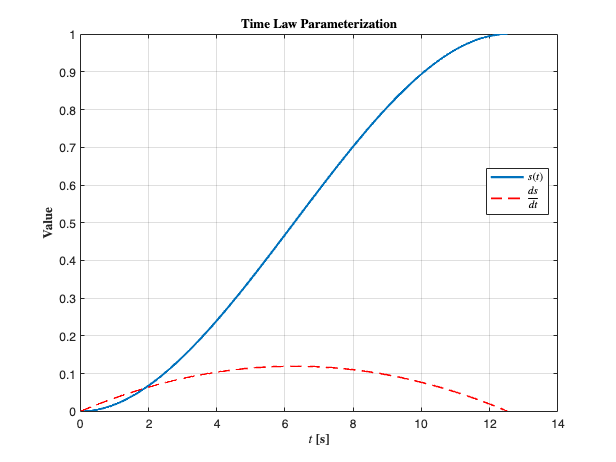

%% PLOTS

%% Plot 1: Path in X-Y plane
fig3 = figure('Color', 'white');
plot(x, y, 'b-', 'LineWidth', 2)
hold on
plot(qi(1), qi(2), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r')
plot(qf(1), qf(2), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g')
% Draw orientation arrows
quiver(qi(1), qi(2), cos(qi(3)), sin(qi(3)), 0.2, 'r', 'LineWidth', 2)
quiver(qf(1), qf(2), cos(qf(3)), sin(qf(3)), 0.2, 'g', 'LineWidth', 2)
title('\textbf{Path in X-Y Plane}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$x$ [m]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$y$ [m]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
axis equal
legend('\textbf{Path}', '\textbf{Initial Point}', '\textbf{Final Point}', 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'best')
set(gca, 'FontSize', fontSize);
% Save in vector format
print(fig3,'-depsc2', 'path_xy_plane.eps');

%% Plot 2: Orientation over time
fig4 = figure('Color', 'white');
plot(t, theta, 'LineWidth', 2)
title('\textbf{Orientation}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$\theta$ [rad]}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
set(gca, 'FontSize', fontSize);
print(fig4,'-depsc2', 'orientation.eps');

%% Plot 3: Time law parameterization
fig5 = figure('Color', 'white');
plot(t, s, 'LineWidth', 2)
hold on
plot(t, ds_dt, 'r--', 'LineWidth', 1.5)
title('\textbf{Time Law Parameterization}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{Value}', 'FontSize', fontSize, 'Interpreter', 'latex')
grid on
legend('\textbf{$s(t)$}', '\textbf{$\frac{ds}{dt}$}', 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'best')
set(gca, 'FontSize', fontSize);
print(fig5,'-depsc2', 'time_law_parameterization.eps');

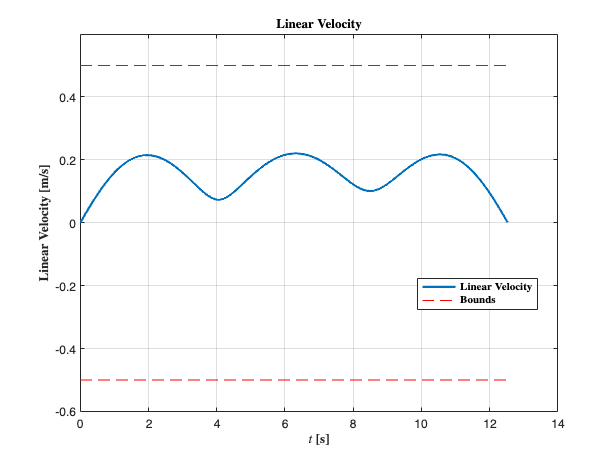


%% Plot 4: Linear velocity over time
fig6 = figure('Color', 'white');
plot(t, v, 'LineWidth', 2)
hold on
plot(t, 0.5*ones(size(t)), 'r--')
plot(t, -0.5*ones(size(t)), 'r--')
title('\textbf{Linear Velocity}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{Linear Velocity [m/s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylim([-0.6, 0.6])
grid on
legend('\textbf{Linear Velocity}', '\textbf{Bounds}', 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'best')
set(gca, 'FontSize', fontSize);
print(fig6,'-depsc2', 'linear_velocity.eps');

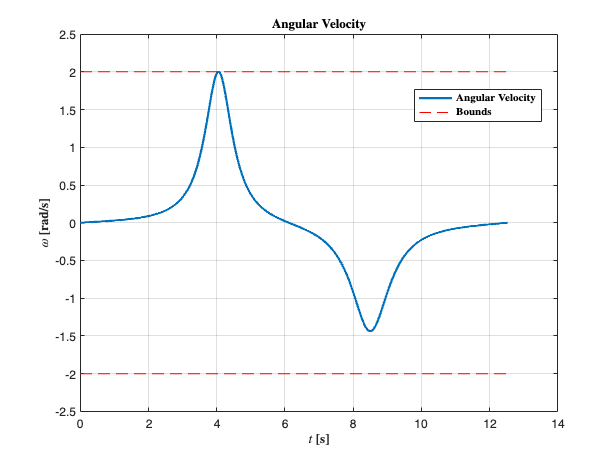


%% Plot 5: Angular velocity over time
fig7 = figure('Color', 'white');
plot(t, omega, 'LineWidth', 2)
hold on
plot(t, 2*ones(size(t)), 'r--')
plot(t, -2*ones(size(t)), 'r--')
title('\textbf{Angular Velocity}', 'FontSize', titleSize, 'Interpreter', 'latex')
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylabel('\textbf{$\omega$ [rad/s]}', 'FontSize', fontSize, 'Interpreter', 'latex')
ylim([-2.5, 2.5])
grid on
legend('\textbf{Angular Velocity}', '\textbf{Bounds}', 'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'best')
set(gca, 'FontSize', fontSize);
print(fig7,'-depsc2', 'angular_velocity.eps');

% %% General settings for all plots
% % Font sizes
% fontSize = 11;
% titleSize = 12;
% legendSize = 10;
% 
% %% Plot 6: Robot motion animation with video export
% figure('Color', 'white', 'Position', [100, 100, 1280, 720]);  % Set figure to HD resolution
% h_fig6 = gcf;
% title('\textbf{Robot Motion Animation}', 'FontSize', titleSize, 'Interpreter', 'latex')
% xlabel('\textbf{$x$ [m]}', 'FontSize', fontSize, 'Interpreter', 'latex')
% ylabel('\textbf{$y$ [m]}', 'FontSize', fontSize, 'Interpreter', 'latex')
% grid on
% axis equal
% axis([min(x)-0.5, max(x)+0.5, min(y)-0.5, max(y)+0.5])
% set(gca, 'FontSize', fontSize);
% 
% % Animation parameters
% robot_size = 0.1;
% 
% % Set up the video writer with MPEG-4 format
% v = VideoWriter('robot_animation.mp4', 'MPEG-4');
% v.FrameRate = 30;  % 30 frames per second for smooth playback
% v.Quality = 95;    % High quality (0-100)
% open(v);           % Open the video file for writing
% 
% % Create a progress bar (optional)
% h_waitbar = waitbar(0, 'Creating animation video...');
% 
% for i = 1:5:length(t)  % Using step of 5 for a good balance of smoothness and file size
%     % Update progress bar
%     waitbar(i/length(t), h_waitbar);
% 
%     % Clear figure but keep the figure handle
%     figure(h_fig6);
%     clf;
% 
%     % Plot the entire path
%     plot(x, y, 'b-', 'LineWidth', 2);
%     hold on;
% 
%     % Plot start and end points
%     plot(qi(1), qi(2), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
%     plot(qf(1), qf(2), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
% 
%     % Draw orientation arrows for start and end points
%     quiver(qi(1), qi(2), cos(qi(3)), sin(qi(3)), 0.2, 'r', 'LineWidth', 2);
%     quiver(qf(1), qf(2), cos(qf(3)), sin(qf(3)), 0.2, 'g', 'LineWidth', 2);
% 
%     % Plot robot as a triangle
%     robot_x = [x(i), x(i) + robot_size*cos(theta(i) + 2*pi/3), x(i) + robot_size*cos(theta(i) - 2*pi/3)];
%     robot_y = [y(i), y(i) + robot_size*sin(theta(i) + 2*pi/3), y(i) + robot_size*sin(theta(i) - 2*pi/3)];
%     fill(robot_x, robot_y, 'r');
% 
%     % Plot orientation arrow for current position
%     quiver(x(i), y(i), 0.2*cos(theta(i)), 0.2*sin(theta(i)), 0, 'r', 'LineWidth', 2);
% 
%     % Add time indicator
%     text(min(x), max(y)+0.2, ['\textbf{Time: }' num2str(t(i), '%.2f') '\textbf{ s}'], ...
%         'FontSize', fontSize, 'Interpreter', 'latex');
% 
%     % Set title, labels, and other properties
%     title('\textbf{Robot Motion Animation}', 'FontSize', titleSize, 'Interpreter', 'latex');
%     xlabel('\textbf{$x$ [m]}', 'FontSize', fontSize, 'Interpreter', 'latex');
%     ylabel('\textbf{$y$ [m]}', 'FontSize', fontSize, 'Interpreter', 'latex');
%     grid on;
%     axis equal;
%     axis([min(x)-0.5, max(x)+0.5, min(y)-0.5, max(y)+0.5]);
% 
%     legend('\textbf{Path}', '\textbf{Initial Point}', '\textbf{Final Point}', ...
%         'FontSize', legendSize, 'Interpreter', 'latex', 'Location', 'best');
%     set(gca, 'FontSize', fontSize);
% 
%     % Ensure all graphics are drawn before capturing
%     drawnow;
% 
%     % Capture the current frame and write it to the video
%     frame = getframe(h_fig6);
%     writeVideo(v, frame);
% end
% 
% % Close the video file
% close(v);
% 
% % Close the progress bar
% if exist('h_waitbar', 'var') && ishandle(h_waitbar)
%     close(h_waitbar);
% end
% 
% % Display a message indicating completion
% disp('Animation video saved as "robot_animation.mp4"');

% Three cases of b for the comparison
b1=-1;
b2=0.2;
b3=0.8;

%Desired positions and orientations
xd=timeseries(x,t);
yd=timeseries(y,t);
thetad=timeseries(theta,t);